## Exercise 5.2)

#### *a)*

Problem Formulation

A = randi(40,10,1)

A =     27
    31
    15
    27
    17
    34
    34
    11
    25
    24


%A(find(cumsum(A(:,2))>=0.49,1),:)

%A(find(sort(A)>=0.5*length(A),1),1)
%A = sort(A)

%A(:,2) = 1/length(A);
%A(find(cumsum(A(:,2))>=0.5,1),:)
p = zeros(length(A),1)

p =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


p(:) = 1/length(A)

p =     0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000


I = find(cumsum(p)>=0.5,1)

I = 5



[B, idx] = sort(A)

B =     11
    15
    17
    24
    25
    27
    27
    31
    34
    34


idx =      8
     3
     5
    10
     9
     1
     4
     2
     6
     7


A(idx==I)

ans = 15

%find(1/sum(length(sort(A)))>=0.5)
quantile(A(:,1), 0.50)

ans = 26

%unidinv(0.50,A(:,1))
icdf('Discrete Uniform',0.5,max(A(:,1)))

ans = 17

out = min(setdiff(A(:),min(A(:))))

out = 15

A

A =     27
    31
    15
    27
    17
    34
    34
    11
    25
    24


#### *b)*

clear;
load data.mat
x = sdpvar(1,8);
S = length(data.f(1,1,:));
alpha = 0.05;
p = zeros(S,1);
p(:) = 1/S;
lambda = 0.2;
R = sdpvar(S,1);
z = sdpvar(S,1);
t = sdpvar(1);
%I = find(cumsum(p,1)>=alpha,1);
%[B, idx] = sort(R);
%t = B(I);

%t = sort(R);
%t = R(I); % Is it I or I-1??
          % Should we sort the R vector (as in the definition of CVaR)?  
Cons = []; 
Cons = [Cons, x * data.c == 50];
Cons = [Cons, x >= 0];
for s=1:S
    Cons = [Cons, x * (sum(data.f(:,:,s).*data.pD(:,s)-(data.f(:,:,s)-data.q(:,:,s)).*data.pI(:,s),1)'-data.pA) == R(s)];
    Cons = [Cons, z(s) >= 0];
    Cons = [Cons, z(s) >= t - R(s)];
end

CVaR = t - (sum(z.*p,1)/alpha);
%Obj = lambda * (x * data.E) + (1-lambda)* CVaR;
Obj = lambda * mean(R) + (1-lambda)* CVaR;

Ops = sdpsettings ('solver','gurobi', 'verbose', 1);


Result = optimize(Cons, -Obj, Ops);

Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 309 rows, 209 columns and 1316 nonzeros
Model fingerprint: 0xa7239ef7
Coefficient statistics:
  Matrix range     [8e-02, 1e+04]
  Objective range  [2e-03, 8e-01]
  Bounds range     [0e+00, 0e+00]
  RHS range        [5e+01, 5e+01]
Presolve removed 208 rows and 100 columns
Presolve time: 0.04s
Presolved: 101 rows, 109 columns, 1008 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0      handle free variables                          0s
      36    2.6431923e+05   0.000000e+00   0.000000e+00      0s

Solved in 36 iterations and 0.07 seconds
Optimal objective  2.643192261e+05


value(Obj)

ans = -2.6432e+05

value(CVaR)

ans = -3.4402e+05

value(t)

ans = -3.1458e+05

TEST

clear;
load data.mat
x = sdpvar(1,8);
S = length(data.f(1,1,:));
alpha = 0.05;
p = zeros(S,1);
p(:) = 1/S;
lambda = 0.2;
R = sdpvar(S,1);
z = sdpvar(S,1);

%I = find(cumsum(p,1)>=alpha,1);
%[B, idx] = sort(R);
%t = B(I);

%t = sort(R);
%t = R(I); % Is it I or I-1??
          % Should we sort the R vector (as in the definition of CVaR)?  
Cons = []; 
Cons = [Cons, x * data.c == 50];
Cons = [Cons, x >= 0];
for s=1:S
    Cons = [Cons, x * (sum(data.f(:,:,s).*data.pD(:,s)-(data.f(:,:,s)-data.q(:,:,s)).*data.pI(:,s),1)'-data.pA) == R(s)];
    Cons = [Cons, z(s) >= 0];
    %Cons = [Cons, z(s) >= data.E(s) - R(s)];
end

Index exceeds the number of array elements (8).


CVaR = data.E - (sum(z.*p,1)/alpha);
Obj = lambda * (x * data.E) + (1-lambda)* CVaR;
%Obj = lambda * mean(R) + (1-lambda)* CVaR;

Ops = sdpsettings ('solver','gurobi', 'verbose', 1);


Result = optimize(Cons, -Obj, Ops);

#### *c)*

clear;
load data.mat
Revenues = [];
lambdas=[];
CVaRs = [];
j = 0;
xVectors = zeros(8,10);
for lambda=0.01:0.1:0.99
j = j+1;
x = sdpvar(1,8);
S = length(data.f(1,1,:));
alpha = 0.05;
p = zeros(S,1);
p(:) = 1/S;
R = sdpvar(S,1);
z = sdpvar(S,1);
t = sdpvar(1);

%I = find(cumsum(p,1)>=alpha,1);
%t = R(I); %Is it I or I-1??

Cons = []; 
Cons = [Cons, x * data.c == 50];
Cons = [Cons, x >= 0];
for s=1:S
    Cons = [Cons, x * (sum(data.f(:,:,s).*data.pD(:,s)-(data.f(:,:,s)-data.q(:,:,s)).*data.pI(:,s),1)'-data.pA) == R(s)];
    Cons = [Cons, z(s) >= 0];
    Cons = [Cons, z(s) >= t - R(s)];
end

CVaR = t - (sum(z.*p,1)/alpha);
Obj = lambda * (x * data.E) + (1-lambda)* CVaR;
%Obj = lambda * mean(R) + (1-lambda)* CVaR;

Ops = sdpsettings ('solver','gurobi', 'verbose', 0);


Result = optimize(Cons, -Obj, Ops);
Revenues = [Revenues, mean(value(R))];
lambdas = [lambdas, value(lambda)];
xVectors(:,j) = value(x)'; 
CVaRs = [CVaRs, value(CVaR)];
end


%figure('Renderer', 'painters', 'Position', [10 10 700 600])
% t = tiledlayout(2,5,"TileSpacing","compact");
% 
% hold on
% for i = 1:length(xVectors)
%     ax = nexttile;
%     pie(ax,xVectors(:,i));
%     title(lambdas(i), " ");
% as
% end
% legend(Labels, 'Location','eastoutside', 'Orientation','vertical')
% %p = pie(xVectors(:,1));
% %legend(Labels, 'Location','eastoutside', 'Orientation','vertical')
% %hold on
% %for i = 2:length(xVectors)
%  %   pie(xVectors(:,i),Labels);
%  %end
%  hold off

xVectors

xVectors =          0         0         0         0         0         0         0         0         0         0
   93.8882   92.7785   80.9801   80.9801   81.4224   78.5847   15.0669    4.5391         0         0
  154.2699  140.7849  128.0693  128.0693  121.3309  102.0736         0         0         0         0
  125.2027  135.7811  144.6905  144.6905  148.8844  164.4076  297.5275  313.6157  314.0149         0
    7.3894   21.4966   23.2984   23.2984   22.2897   21.8834   43.8077   39.5555         0         0
   13.1185    3.1918         0         0         0         0         0         0         0         0
   62.0437   56.0595   62.2384   62.2384   64.5306   65.9907    6.9384         0         0         0
         0    2.9131   11.9641   11.9641   12.6660   18.5417  108.1383  122.2469  219.6932  632.1474


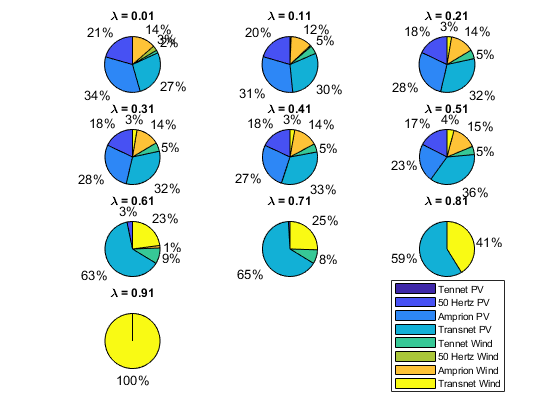

Labels = ["Tennet PV", "50 Hertz PV", "Amprion PV", "Transnet PV", "Tennet Wind", "50 Hertz Wind", "Amprion Wind", "Transnet Wind"];
for i=1:length(xVectors)
 subplot(4,3,i)
 p = pie(xVectors(:,i));
 th = findobj(p,'Type','Text');
 isSmall = startsWith({th.String}, '<');
 isZero = startsWith({th.String}, '0');
 set(th(isZero), 'String', '');
 set(th(isSmall),'String', '');
 title("\lambda = " + lambdas(i), 'Position',[0 1.5]);
 end
hl = legend(Labels, 'Location','eastoutside', 'Orientation','vertical');
newPosition = [0.75 0.15 0.1 0.1];
newUnits = 'normalized';
set(hl,'Position', newPosition,'Units', newUnits)

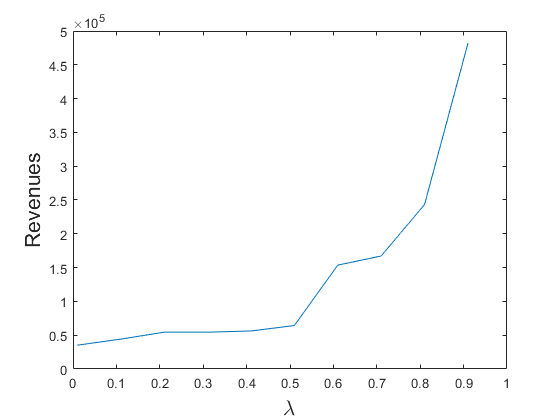

clf;
plot(lambdas,Revenues)

xlabel('\lambda', 'Fontsize',16)
ylabel('Revenues', 'Fontsize', 16)

#### d)

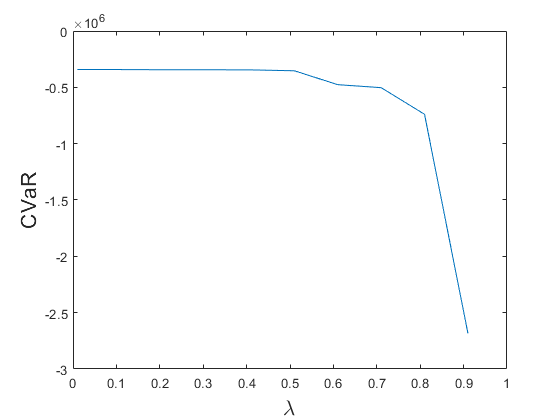

clf;
plot(lambdas,CVaRs);
xlabel('\lambda', 'Fontsize',16)
ylabel('CVaR', 'Fontsize', 16)

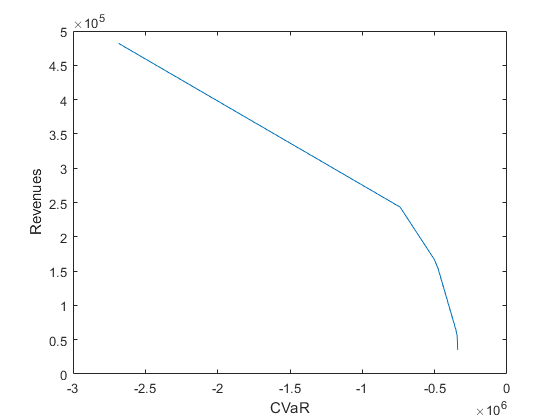

clf;
plot(CVaRs,Revenues)
xlabel('CVaR', 'FontSize',16)
ylabel('Revenues', 'FontSize',16)

## Exercise 5.3)

#### *a)*

#### b)

clear;
load data_farmer_cvar.mat;
alpha = 0.05;
lambda = 0.5;
S = length(yields);
R = sdpvar(S,1);
x = sdpvar(3,1);
w_W = sdpvar(S,1); w_C = sdpvar(S,1);
e_H = sdpvar(S,1); e_L = sdpvar(S,1);
y_W = sdpvar(S,1); y_C = sdpvar(S,1);
t = sdpvar;
z = sdpvar(S,1);
p = zeros(S,1);
p(:) = 1/S;

Costs = [150 230 260]; %W;C;B
Cons = [];
Cons = [Cons, sum(x) <= 500];
for s=1:S
    Cons = [Cons, yields(s,1)* x(1) + y_W(s) - w_W(s) == 200];
    Cons = [Cons, yields(s,2)* x(2) + y_C(s) - w_C(s) == 240];
    Cons = [Cons, yields(s,3)* x(3) - e_H(s) - e_L(s) == 0];
    Cons = [Cons, e_H(s)<=6000];
    Cons = [Cons, R(s) == ((170 * w_W(s) + 150 * w_C(s) + 36 * e_H(s) + 10 * e_L(s) - 238 * y_W(s) - 210*y_C(s)) - Costs*x)];
    Cons = [Cons, [w_W(s); w_C(s); e_H(s); e_L(s); y_W(s); y_C(s)] >=0 ];
    Cons = [Cons, z(s)>= 0];
    Cons = [Cons, z(s) >= t - R(s)];
end
Cons = [Cons, x>=0];

CVaR = t - (sum(z.*p,1)/alpha);
Obj = lambda * mean(R) + (1-lambda)*CVaR;

Ops = sdpsettings ('solver','gurobi', 'verbose', 1);
Result = optimize(Cons, -Obj, Ops);

Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 13004 rows, 8004 columns and 30006 nonzeros
Model fingerprint: 0xaf4447ba
Coefficient statistics:
  Matrix range     [9e-01, 3e+02]
  Objective range  [5e-04, 5e-01]
  Bounds range     [0e+00, 0e+00]
  RHS range        [2e+02, 6e+03]

Concurrent LP optimizer: dual simplex and barrier
Showing barrier log only...

Presolve removed 9003 rows and 1000 columns
Presolve time: 0.05s
Presolved: 4001 rows, 7004 columns, 20003 nonzeros

Ordering time: 0.00s

Barrier statistics:
 Dense cols : 4
 Free vars  : 1
 AA' NZ     : 1.000e+04
 Factor NZ  : 2.601e+04 (roughly 5 MBytes of memory)
 Factor Ops : 1.740e+05 (less than 1 second per iteration)
 Threads    : 1

                  Objective                Residual
Iter       Primal          Dual         Primal    Dual     Compl     

value(Obj)

ans = 2.3624e+03

value(mean(R))

Unrecognized function or variable 'Revenues'.

value(CVaR)

#### c)

clear;
load data_farmer_cvar.mat;
alpha = 0.05;
Revenues = [];
lambdas=[];
CVaRs = [];
j = 0;
xVectors = zeros(3,10);
for lambda=0.01:0.1:0.99
j = j+1;
%lambda = 0.5;
S = length(yields);
R = sdpvar(S,1);
x = sdpvar(3,1);
w_W = sdpvar(S,1); w_C = sdpvar(S,1);
e_H = sdpvar(S,1); e_L = sdpvar(S,1);
y_W = sdpvar(S,1); y_C = sdpvar(S,1);
t = sdpvar;
z = sdpvar(S,1);
p = zeros(S,1);
p(:) = 1/S;

Costs = [150 230 260]; %W;C;B
Cons = [];
Cons = [Cons, sum(x) <= 500];
for s=1:S
    Cons = [Cons, yields(s,1)* x(1) + y_W(s) - w_W(s) == 200];
    Cons = [Cons, yields(s,2)* x(2) + y_C(s) - w_C(s) == 240];
    Cons = [Cons, yields(s,3)* x(3) - e_H(s) - e_L(s) == 0];
    Cons = [Cons, e_H(s)<=6000];
    Cons = [Cons, R(s) == ((170 * w_W(s) + 150 * w_C(s) + 36 * e_H(s) + 10 * e_L(s) - 238 * y_W(s) - 210*y_C(s)) - Costs*x)];
    Cons = [Cons, [w_W(s); w_C(s); e_H(s); e_L(s); y_W(s); y_C(s)] >=0 ];
    Cons = [Cons, z(s)>= 0];
    Cons = [Cons, z(s) >= t - R(s)];
end
Cons = [Cons, x>=0];

CVaR = t - (sum(z.*p,1)/alpha);
Obj = lambda * mean(R) + (1-lambda)*CVaR;

Ops = sdpsettings ('solver','gurobi', 'verbose', 1);
Result = optimize(Cons, -Obj, Ops);

Revenues = [Revenues, mean(value(R))];
lambdas = [lambdas, value(lambda)];
CVaRs = [CVaRs, value(CVaR)];
xVectors(:,j) = value(x)';
end

Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 13004 rows, 8004 columns and 30006 nonzeros
Model fingerprint: 0x6e9392c5
Coefficient statistics:
  Matrix range     [9e-01, 3e+02]
  Objective range  [1e-05, 1e+00]
  Bounds range     [0e+00, 0e+00]
  RHS range        [2e+02, 6e+03]

Concurrent LP optimizer: dual simplex and barrier
Showing barrier log only...

Presolve removed 9003 rows and 1000 columns
Presolve time: 0.07s
Presolved: 4001 rows, 7004 columns, 20003 nonzeros

Ordering time: 0.00s

Barrier statistics:
 Dense cols : 4
 Free vars  : 1
 AA' NZ     : 1.000e+04
 Factor NZ  : 2.601e+04 (roughly 5 MBytes of memory)
 Factor Ops : 1.740e+05 (less than 1 second per iteration)
 Threads    : 1

                  Objective                Residual
Iter       Primal          Dual         Primal    Dual     Compl     

#### d)

Labels = ["Wheat", "Corn", "Sugar Beet"];
for i=1:length(xVectors)
 subplot(4,3,i)
 p = pie(xVectors(:,i));
 th = findobj(p,'Type','Text');
 isSmall = startsWith({th.String}, '<');
 isZero = startsWith({th.String}, '0');
 set(th(isZero), 'String', '');
 set(th(isSmall),'String', '');
 title("\lambda = " + lambdas(i), 'Position',[0 1.5]);
 end

Unrecognized function or variable 'xVectors'.

hl = legend(Labels, 'Location','eastoutside', 'Orientation','vertical');
newPosition = [0.75 0.15 0.1 0.1];
newUnits = 'normalized';
set(hl,'Position', newPosition,'Units', newUnits)
clf;
plot(lambdas,Revenues)

xlabel('\lambda', 'Fontsize',16)
ylabel('Revenues', 'Fontsize', 16)

#### d)

clf;
plot(lambdas,value(CVaRs));
xlabel('\lambda', 'Fontsize',16)
ylabel('CVaR', 'Fontsize', 16)
clf;
plot(value(CVaRs),Revenues);
xlabel('CVaR', 'FontSize',16)
ylabel('Revenues', 'FontSize',16);

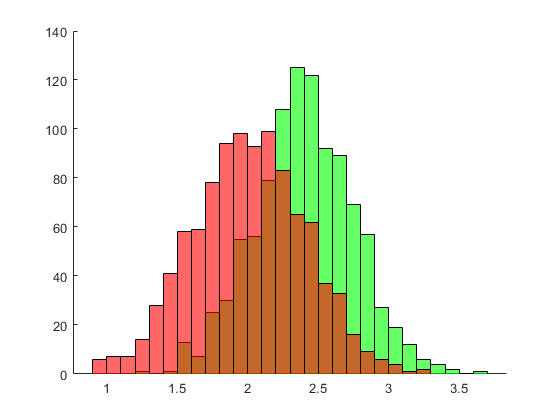

clf;
histogram(yields(:,3),'FaceColor','r')
hold on
histogram(yields(:,2),'FaceColor','g')
histogram(yields(:,1),'FaceColor','r')
hold off